clear all;close all;clc;
load data/horse.mat

%recorder = audiorecorder(Fs, 16, 1);
% recorder.StartFcn = 'disp(''Start speaking.'')';
% recorder.StopFcn = 'disp(''End of recording.'')';

%record(recorder, 7);
%pause(5)
% disp('A')
% play(recorder)
% pause(7)
% disp('B')
%y_r = getaudiodata(recorder);

[y_r, Fs] = audioread('data/horse.wav');

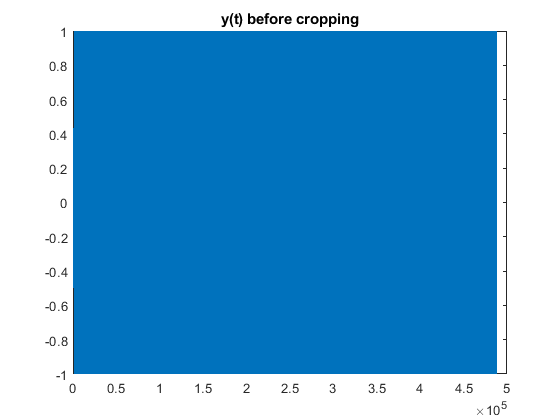

f_c = 1000;
figure()
plot(y_r)
title("y(t) before cropping")

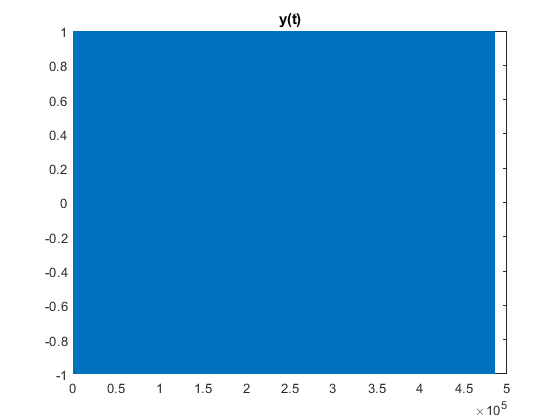


start_idx = find_start_of_signal(y_r,x_sync);
y_x = y_r(start_idx+length(x_sync):end); 
y_t = y_x(1:msg_length*8*100);
figure()
plot(y_t)
title("y(t)")

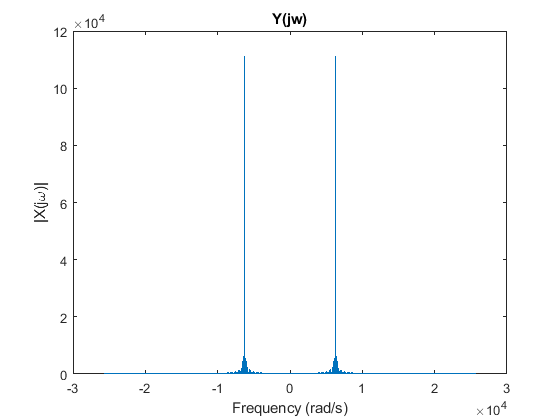

figure()
plot_ft_rad(y_t, Fs);
title("Y(jw)")

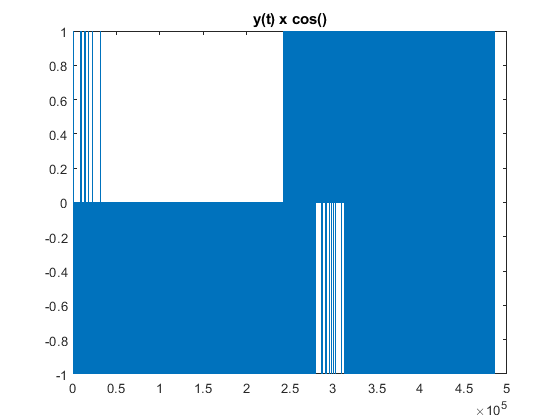


%Multiply Singal with Cosine function
c = cos(2*pi*f_c/Fs*[0:length(y_t)-1]');
y_d = y_t .* c;
figure()
plot(y_d)
title("y(t) x cos()")

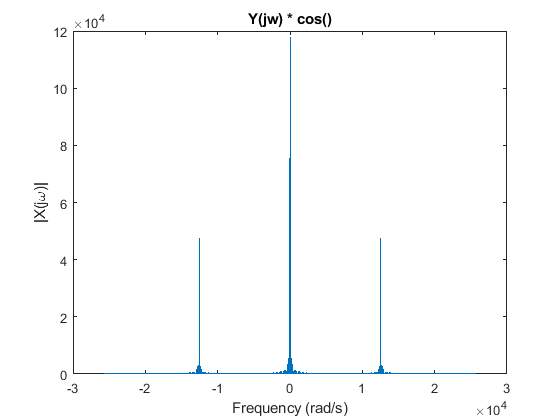

figure()
plot_ft_rad(y_d, Fs);
title("Y(jw) * cos()")

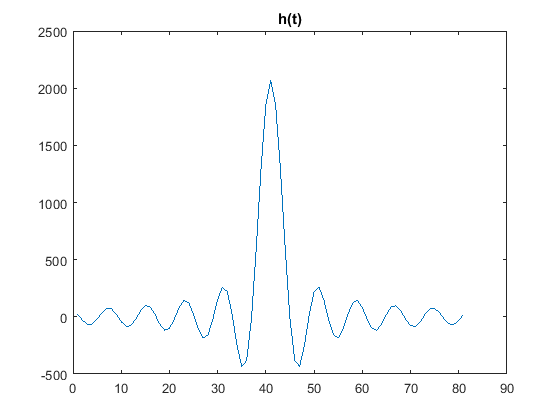


%Create Low-Pass Filter
W = 6500;
t = [-40:1:40]*(1/Fs);
h = W/pi*sinc(W/pi.*t);
figure()
plot(h)
title("h(t)")

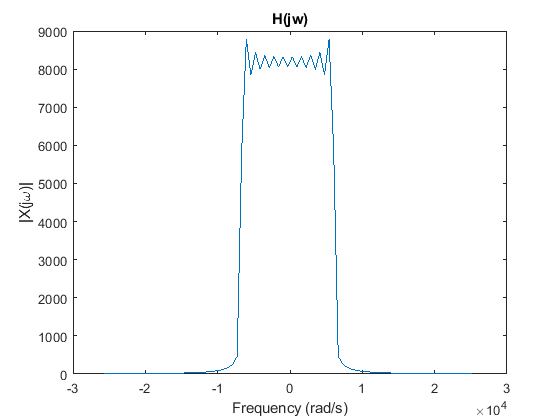

figure()
plot_ft_rad(h, Fs);
title("H(jw)")

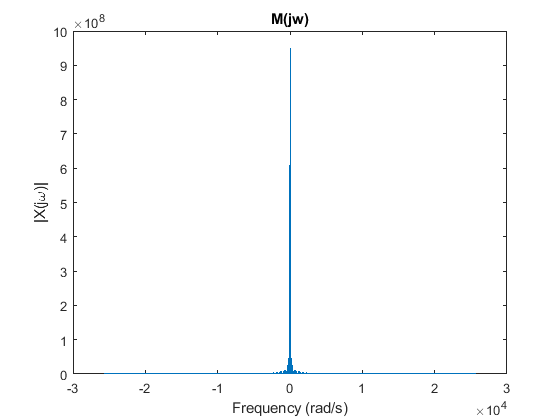


%Convolve with LPF
x_t = conv(y_d,h);
figure()
plot_ft_rad(x_t, Fs);
title("M(jw)")

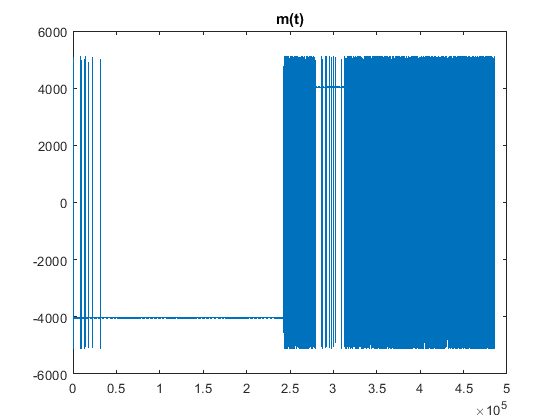

figure()
plot(x_t)
title("m(t)")

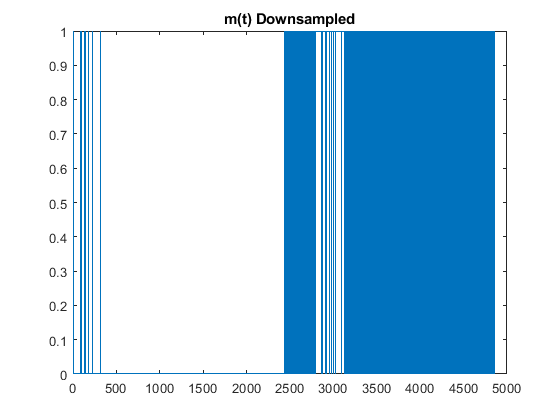


%Normalize Singal to Interpret it
x_d = downsample(((square(x_t/400) + 1)./2),100);

% If signal needs to be flipped uncomment
x_d = mod(x_d+1, 2);

figure()
plot(x_d)
title("m(t) Downsampled")

Message = BitsToString(x_d(2:end))

Error using reshape
Size arguments must be real integers.

Error in BitsToString (line 8)
binary_chars = reshape(binary, sz_binary/8, 8);